% Load data and avoid reloading every time
if ~exist('mnist_load','var')
    mnist = csvread('mnist_train.csv', 1, 0);
    mnist_load = 1;
end

clc 
close all
warning('off')

**Exercise 1**

(10 pts program + 5 pts solution) Let 𝑈 and 𝑊 be subspaces of ℝ5 that are spanned, respectively, by the columns of the matrices 𝐴 and 𝐵 (shown below). Write a function `altproj(A,B,v0,n)` that returns 𝑣⎯_2𝑛 after 2𝑛 steps of alternating projection onto 𝑈 and 𝑊 starting from 𝑣_0. Use this function to find the orthogonal projection of 𝑣_0 (shown below) onto 𝑈∩𝑊. How large should 𝑛n be chosen so that the projection is correct to 4 decimal places (e.g., absolute error at most 0.0001 in each coordinate)?

To find the intersection of 𝑈 and 𝑊, we note that the following Python snippet returns a matrix whose columns span 𝑈∩𝑊

`basis_UintW = np.hstack([A, B]) @ null_space(np.hstack([A, -B])) `

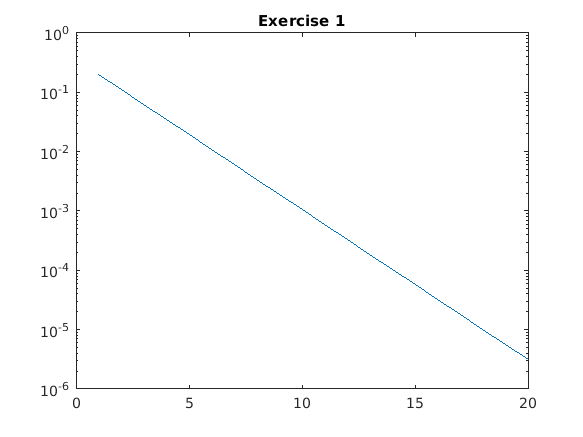

%% Exercise 1
    % Let U and W be subspaces of R^5 that are spanned, respectively, by
    % the columns of the matrices A and $B$ (shown below)
    % Write a function `altproj(A,B,v0,n)` that returns v_{2n} after 2n 
    % steps of alternating projection onto U and W starting from v_0.
    % Use this function to find the orthogonal projection of v0 (shown 
    % below) onto $ U \cap W $. 
    % How large should n be chosen so that the projection is correct to 4 
    % decimal places (e.g., absolute error at most 0.0001 in each 
    % coordinate)?
    A = [3, 2, 3; 1, 5, 7; 4, 11, 13; 1, 17, 19; 5, 23, 29];
    B = [1, 1, 2.5; 2, 0, 6; 2, 1, 12; 2, 0, 18; 6, -3, 26];
    v0 = [1; 2; 3; 4; 5];
    n = 20;
    [~, err] = altproj(A, B, v0, n);
    
    figure
    semilogy(1:n, err)
    title('Exercise 1')

From the result we can observe that the sequence $v_n$ converges to its projection onto intersection of U and W.

**Exercise 2**

(10 pts program + 5 pts solution) Write a function `kaczmarz(A,b,I)` that returns a matrix 𝑋X with 𝐼I columns corresponding to the Kaczmarz iteration after 𝑖=1,2,...,𝐼 full passes through the Kaczmarz algorithm for the matrix 𝐴A and right-hand side 𝑏(e.g., one full pass equals 𝑚 steps). Use this function to find the minimum-norm solution of linear system 𝐴𝑥=𝑏.

Plot the error (on a log scale) versus the number of full passes for 𝐼=500.

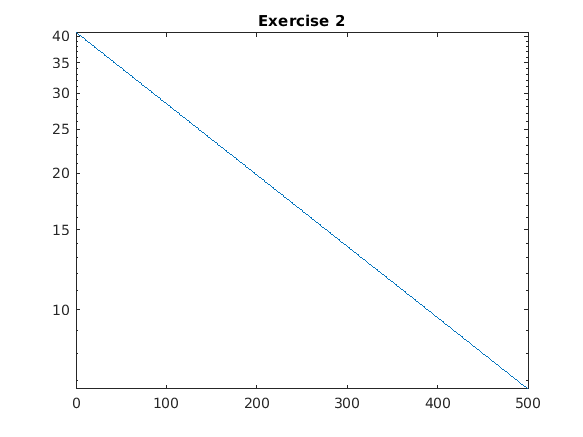

%% Exercise 2
    % Write a function `kaczmarz(A,b,I)` that returns a matrix X with I 
    % columns corresponding to the Kaczmarz iteration after i = 1, ..., I 
    % full passes through the Kaczmarz algorithm for the matrix A and 
    % right-hand side b (e.g., one full pass equals m steps). 
    % Use this function to find the minimum-norm solution of linear system 
    % Ax = b
    A = [2, 5, 11, 17, 23; 3, 7, 13, 19, 29];
    b = [228; 227];
    I = 500;
    [~, err] = kaczmarz(A, b, I);
    
    figure(2)
    semilogy(1:I, err)
    title('Exercise 2')

**Exercise 3**

(10 pts) Repeat the experiment with 𝐼=100 for a random system defined by `A = randn(500,1000)` and `b = A @ randn(1000)`. Compare the iterative solution with the true minimum-norm solution .

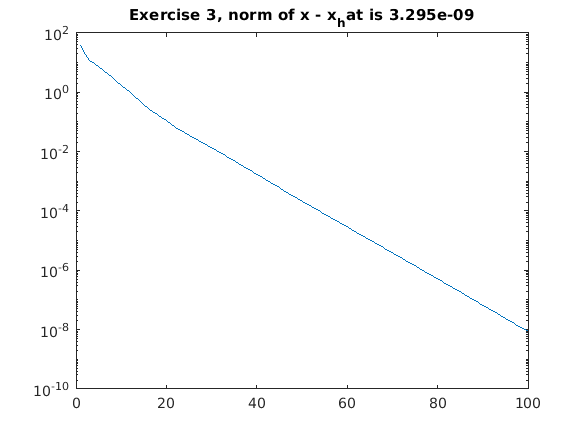

%% Exercise 3
    % Repeat the experiment with I=100 for a random system defined by 
    % `A = randn(500,1000)` and `b = A * randn(1000,1)`. 
    % Compare the iterative solution with the true minimum-norm solution 
    % x_hat = A^H {(A A^H)}^{-1} b $.
    A = randn(500, 1000);
    b = A * randn(1000, 1);
    I = 100;
    [X, err] = kaczmarz(A, b, I);
    
    x_hat = A'* inv(A* A')* b ;
    diff = norm(x_hat - X(:, end));
    figure(3)
    semilogy(1:I, err)
    title(sprintf('Exercise 3, norm of x - x_hat is %.4g', diff))

    From the graph we plotted above we can observe that:

To make the projection is correct to 4 decimal places, n sould be at least 14 (approximate number directly obsrved from the graph).

    From  Excercise 2 and Excercise 3  we can tell that the sequence generated by alternating projection (iterative solution) converges to the true minimum solution $\overset{\Lambda }{x} {=A}^H {\textrm{（A}A^H ）}^{-1} b$.

**Exercise 4**

(10 pts program + 5 pts solution) Consider the linear program

min 𝑐⎯⎯𝑇𝑥subject to𝐴𝑥≥𝑏⎯⎯,𝑥⎯⎯≥0min c_Tx_subject toAx_≥b_,x_≥0with

Let 𝑝∗p∗ denote the optimum value of this program. Then, 𝑝∗≤0p∗≤0 is satisfied if and only if there is a non-negative 𝑥⎯⎯=(𝑥1,𝑥2,𝑥3)𝑇x_=(x1,x2,x3)T satisfying

2x1 - x2 + x3 >=-1

x1 + 2x3 >=2

-7x1 + 4x2 -6x3 >=1

-3x1 + x2 -2x3 >= 0 

where the last inequality restricts the value of the program to be at most 0. One can find the optimum value `p` and an optimizer `x` with the command

`res = linprog(c, A_ub=-A, b_ub=-b, bounds=[(0, None)] * c.size, method=’interior-point’) x, p = res.x, res.fun`

Starting from x_0=0, write a program that uses alternating projections onto half spaces (see (6)) to find a non-negative vector satisfying the above inequalities.

Warning: don’t forget to also project onto the half spaces defined by the non-negativity constraints 𝑥1≥0,𝑥2≥0,𝑥3≥0.

Use the result to find a vector that satisfies all the inequalities. How many iterations are required so that the absolute error is at most 0.0001 in each coordinate?

%% Exercise 4
    % Consider the linear program
    % min c^T x   subject to   A x >= b,   x >= 0
    % with c, A, b given below.
    % Let p^* denote the optimum value of this program.
    % Then, p^* <=e 0 is satisfied if and only if there is a non-negative 
    % x = [x_1, x_2, x_3]^T satisfying
    %      2x_1 -  x_2 +  x_3 >= -1
    %       x_1        + 2x_3 >=  2
    %     -7x_1 + 4x_2 - 6x_3 >=  1
    %     -3x_1 +  x_2 - 2x_3 >=  0
    % where the last inequality restricts the value of the program to be at
    % most 0. One can find the optimum value p and an optimizer x with the 
    % command 
    %     [x,p]=linprog(c,-A,-b,[],[],zeros(1,length(c)),[])
    %
    % Starting from x_0=0, write a program that uses alternating projection
    % onto half spaces (see (6)) to find a non-negative vector satisfying 
    % the above inequalities. 
    %
    % Write a function `lp_altproj(A,b,I)` that uses alternating projection
    % with I passes through entire set of inequality constraints, to find a 
    % non-negative vector x that satisfies A x >= b.
    % 
    % Warning: don?t forget to also project onto the half spaces defined by
    % the non-negativity constraints x_1 >= 0, x_2 >= 0, x_3 >= 0. 
    % 
    % Use the result to find a vector that satisfies all the inequalities. 
    % How many iterations are required so that the absolute error is at 
    % most 0.0001 in each coordinate?
    c = [3; -1; 2];
    A = [2, -1, 1; 1, 0, 2; -7, 4, -6];
    b = [-1; 2; 1];
    
    % Do not forget constraint xi >= 0
    A1 = [2, -1, 1; 1, 0, 2; -7, 4, 6; -3, 1, -2; 1, 0, 0; 0, 1, 0; 0, 0, 1];
    b1 = [-1; 2; 1; 0; 0; 0; 0];
    I = 1000;
    [xlinprog, ~] = linprog(c, -A, -b, [], [], zeros(1, length(c)), []);


Optimal solution found.



    disp(xlinprog)

         0
    2.0000
    1.0000



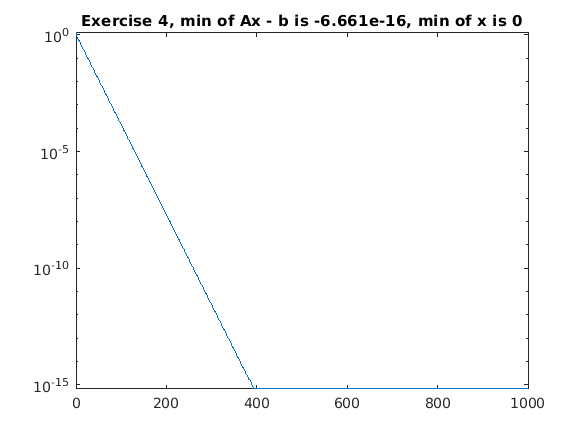

    [x, err] = lp_altproj(A1, b1 , I, 1);
    
    figure(4)
    semilogy(1:I, err)
    title(sprintf('Exercise 4, min of Ax - b is %.4g, min of x is %.4g', min(A*x - b), min(x)))

    From the graph we plotted above we can observe that:

    To make the projection is correct to 4 decimal places, n sould be at least 111 (approximate number directly obsrved from the graph).

    From this problem we can tell that the result we find by using alternating projection onto half spaces converges to the result by calling *linprog()。*

    We noticed that the minimum value of Ax -b is a very small negative number that is because different from Exercise 5, in 4 we didn't add some small $\varepsilon >0$, so we got an "almost feasible x". To find an strictly feasible point, we need to add that small bias, as we showed in Excercise 5.

**Exercise 5**

(10 pts + 5 pts for value and strict feasibililty point) Consider the “random” convex optimization problem defined by

`c = randn(1000) A = np.vstack([-np.ones((1, 1000)), randn(500, 1000)]) b = np.concatenate([[-1000], A[1:] @ rand(1000)])`

Modify 𝐴 and 𝑏 (by adding one row and one element) so that your function can be used to prove that the value of the convex optimization problem, in (3), is at most −1000. Try using `I = 1000` passes through all 501 inequality constraints. This type of iteration typically terminates with an “almost feasible” 𝑥_. To find a strictly feasible point, try running the same algorithm with the argument 𝑏_+𝜖 for some small 𝜖>0ϵ>0 (e.g., try 𝜖=10^−6). Then, the resulting 𝑥⎯⎯x_ can satisfy `np.all(A @ x - b > 0)`

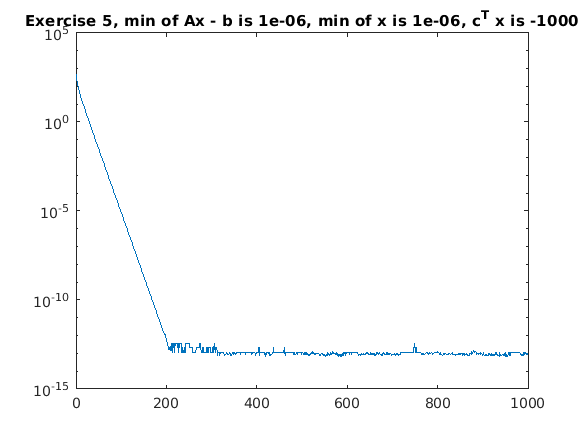

%% Exercise 5
    % Consider the ?random? convex optimization problem defined by c, A, b
    % below. Modify A and b (by adding one row and one element) so that 
    % your function can be used to prove that the value of the convex
    % optimization problem, in (3), is at most ?1000. Try using I=1000 
    % passes through all 501 inequality constraints.
    % This type of iteration typically terminates with an ?almost feasible?
    % x. To find a strictly feasible point, try running the same algorithm 
    % with the argument b + epsilon for some small epsilon > 0  (e.g., try 
    % epsilon = 1e-6). Then, the resulting x can satisfy `all(A*x - b > 0)`
    rng(0, 'twister');
    c = randn(1000, 1);
    A = [ones(1, 1000); randn(500, 1000)];
    b = [-1000; A(2:end, :) * rand(1000, 1)];
    
    % Do not forget constraint xi >= 0 and c^T x <= -1000
    A1 = [A; -c'; eye(1000)];
    b1 = [b; 1000; zeros(1000, 1)];
    I = 1000;
    [x, err] = lp_altproj(A1, b1 + 1e-6 , I, 1);
    
    figure(5)
    semilogy(1:I, err)
    title(sprintf('Exercise 5, min of Ax - b is %.4g, min of x is %.4g, c^T x is %.4g', ...
        min(A*x - b), min(x), dot(c, x)))

all(x > 0)

ans = logical
   1


all((A*x -b) > 0)

ans = logical
   1


    By adding a small $\varepsilon >0$ to, we get a strictly feasble point in Excercise 5.

    Tested by all(x > 0)  and all ((A*x -b) > 0), we were sure that all the constraints are satisfied.

**Exercise 6**

(10 pts) Repeat the MNIST training exercise from the Least-Squares Handout using the training method described above. First, extract the indices of all the 2’s and randomly separate the samples into equal-sized training and testing groups. Second, do the same for the 3’s. Now, extend each vector to length 785 by appending a −1. This will allow the system to learn a general hyperplane separation.

Next, use alternating projections to design a linear classifier to separate for 2’s and 3’s. For the resulting linear function, report the classification error rate and confusion matrices for the both the training and test sets. Is there any benefit to choosing 𝑠<1? Also, for the test set, compute the histogram of the function output separately for each class and then plot the two histograms together. This shows easy or hard it is to separate the two classes.

Depending on your randomized separation into training and test sets, the training data may or may not be linearly separable. Comment on what happens to the test set performance when the error rate does converge to zero for the training set.

 %% Exercise 6
    % Repeat the MNIST training exercise from the Least-Squares Handout 
    % using the training method described above. First, extract the indices 
    % of all the 0?s and randomly separate the samples into equal-sized 
    % training and testing groups. Second, do the same for the 1?s. Now, 
    % extend each vector to length 785 by appending a ?1. This will allow 
    % the system to learn a general hyperplane separation.
    %
    % Next, use alternating projections to design a linear classifier to 
    % separate for 0?s and 1?s. For the resulting linear function, report 
    % the classification error rate and confusion matrices for the both the 
    % training and test sets. Also, for the test set, compute the histogram
    % of the function output separately for each class and then plot the 
    % two histograms together. This shows easy or hard it is to separate 
    % the two classes.
    % 
    % Depending on your randomized separation into training and test sets, 
    % the training data may or may not be linearly separable. Comment on 
    % what happens to the test set performance when the error rate does 
    % converge to zero for the training set.
    fprintf('\nExercise 6\n')


Exercise 6


Pairwise experiment, mapping 0 to -1, mapping 1 to 1
training error = 0.00%, testing error = 0.09%
Confusion matrix for training set:
        2066           0
           0        2342

Confusion matrix for testing set:
        2063           3
           1        2341



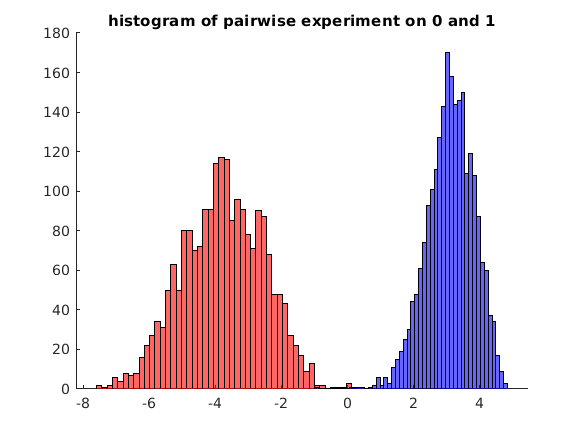

    solver = @ (A, b) lp_altproj(A, b + 1e-6, 500, 1);
    mnist_pairwise_altproj(mnist, 0, 1, solver, 0.5, true);

Pairwise experiment, mapping 2 to -1, mapping 3 to 1
training error = 10.11%, testing error = 10.93%
Confusion matrix for training set:
        1657         431
           0        2175

Confusion matrix for testing set:
        1641         447
          19        2156



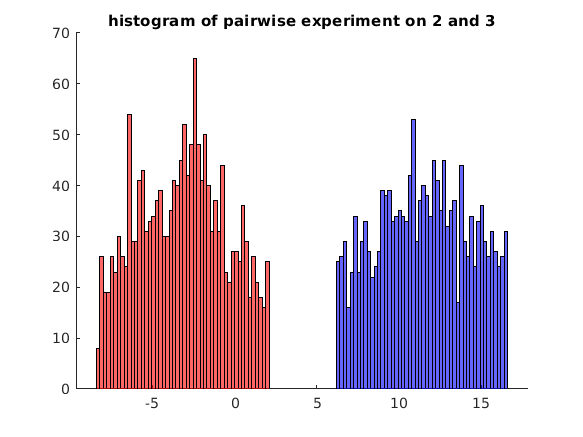

    mnist_pairwise_altproj(mnist, 2, 3, solver, 0.5, true);

    We can tell that the classification performance of pairs of digits varies by choosing different pairs of digits. That's because there are some pair of digits that looks very different eg. 0 and 2; some digits are very similiar, eg 2 and 3.

    To improve the pairwise classification  performance, there are mainly two different ways:

- Increasing the iteration number I, which will consume much more time

- Making step size s smaller than 1, which will also make the program consume more time but not as much as the first way.

    So, what happens to the test set performance when the error rate converges to zero for the training set?

    We experiments, we can tell that even the error rate converges to zero for training set, the error rate of testing set will decrease at first but may converges to some value that doesn't neccessarily to be zero. This phenomenon happens because of overfitting especially when we have have many features but the training set is not large enough.

**Exercise 7**

(10 pts program + 10 pts solution) Describe how this approach should be extended to multi-class linear classification (parameterized by 𝑍∈ℝ where the classifier maps a vector 𝑣_ to class 𝑗 if the 𝑗-th element of 𝑍𝑇𝑣_ is the largest element in the vector. Use the implied alternating-projection solution to design a multi-class classifier for MNIST. Is there any benefit to choosing 𝑠<1?

     % Exercise 7
%     Describe how this approach should be extended to multi-class linear 
%     classification (parameterized by X in R^{n x d}) where the classifier 
%     maps a vector v to class j if the j-th element of X^T v is the 
%     largest element in the vector. Use the implied alternating-projection 
%     solution to design a multi-class classifier for MNIST.
    fprintf('\nExercise 7\n')


Exercise 7


training error = 13.05%, testing error = 15.48%
Confusion matrix for training set:
        1991           0           7           0           0           0           0           0           0           3
           0        2287           9           5           6           6           8           4          12           4
          29          88        1703          45          44           8          64          32          66           9
           0          50          64        1846          12          42          18          41          47          42
           6          35          17           0        1823          19          12           6          13         105
          46          33           5         156          39        1407          68          13          86          44
          38          20          15           1          22          33        1928           0          11           0
          18          69          18           9          58          

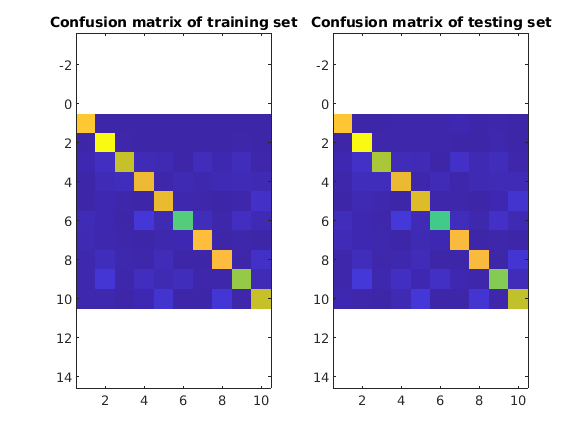

    if exist('cm_te.mat','file') && exist('cm_tr.mat','file')
        out = matfile("cm_te.mat");
        out1 = matfile("cm_tr.mat");
        cm_tr = out1.cm1;
        cm_te = out.cm;
        compute_err(cm_tr, cm_te);
    else
        solver = @ (A, b) lp_altproj(A, b + 1e-6, 100);
        mnist_multiclass_altproj(mnist, solver, 0.5);
    end

    So is there any benefits to choosing smaller than 1?

    As we observed from Exercise 6 and 7 choosing step size smaller than 1 will apparently help with decreasing the classification error. Too large step size may make our sequence "jump over" the optimum solution, so smaller step size can make our results "finer", though a smaller step size s also indicate a longer running time of our program.   

     When I was doing Excercise 7 the biggest problem I encountered was that I encountered the error: Requested (111GB) array exeeds the maximum  array size preference, even though I modified the preference to allow it exceed my computer memory(8GB). The program was unbeleivable slow. So I modified the code above. Once I succeeded in running the code I would store the output data into two .mat file. So It won't take me too much time to run this piece of code again every time. If the code have never been ran before,it will call the server to solve the problem. I strongly suggest you to include thw cm_te.mat and cm_tr.mat in your current folder,other wise this part of code will take at least 1 hour in matlab. 

function [v, err] = altproj(A, B, v0, n)
% Arguments:
%     A -- matrix whose column span is vector space U
%     B -- matrix whose column span is vector space W
%     v0 -- initialization vector
%     n -- number of sweeps for alternating projection
% Returns:
%     v -- the output after 2n steps of alternating projection
%     err -- the error after each full pass
    % Construct projection matrix
    PU = A* inv(A'* A)* A'; 
    PW = B* inv(B'* B)* B';
    
    % Compute the exact solution
    basis_UintW = [A B]* null([A -B], 'r');
    P_UintW = basis_UintW* inv(basis_UintW'* basis_UintW)* basis_UintW';
    v_star = P_UintW* v0;
    
    % Apply n full pass of alternating projection
    v = v0;
    err = zeros(1, n);
    for t = 0:(2*n -1)
        if mod(t, 2) == 0 %project onto U when t is even and W when t is odd
            v = PU*v;
        else
            v = PW*v;
        end
        if mod(t+1, 2) == 0
            err(floor(t/2) + 1) = max(v - v_star); %compute the err
        end
    end
end

function [X, err] = kaczmarz(A, b, I)
% Arguments:
%     A -- matrix defines the LHS of linear equation
%     b -- vector defines the RHS of linear equation
%     I -- number of full passes through the Kaczmarz algorithm
%     S -- step size
% Returns:
%     X -- the output of all I full passes
%     err -- the error after each full pass
    [m, n] = size(A);
    v = zeros(n, 1);
    X = zeros(n, I);
    err = zeros(1, I);
    v_star = A'* inv(A* A')* b;  %compute the precise result
    for i = 0 : I* m
        ai = A(mod(i,m) + 1,:);
        bi = b(mod(i,m) + 1);
        v = v - (ai'*(ai*v - bi)/(ai * ai'));
        if mod(i+1, m) == 0     %after each sweep we store the err and updated v
            err(floor(i/m) + 1) = max(abs(A*v - b));
            X(:, floor(i/m) + 1) = v;
        end
    end
end

function p = proj_HS(v, w, c)
% Projection on half space defined by {v| <v,w> = c}
% Arguments:
%     v -- vector to be projected
%     w -- norm vector of hyperplane
%     c -- intercept
% Returns:
%     p -- orthogonal projection of x on half-space <v|w> >= c
if w* v >= c
    p = v;
else
    p = v - (w'*(w*v - c)/(w * w'));
end
    
end

function [v, err] = lp_altproj(A, b, I, s)
% Find a feasible solution for A v >= b using alternating projection
% Arguments:
%     A -- matrix defines the LHS of linear equation
%     b -- vector defines the RHS of linear equation
%     I -- number of full passes through the alternating projection
%     c -- coefficient of the thing we need to minimize
% Returns:
%     v -- the output after I full passes
%     err -- the error after each full pass
    [m, n] = size(A);
    % Apply I sweeps of alternating projection
    v = zeros(n, 1);
    err = zeros(1, I);
    for t = 0 : (I*m) -1
        ai = A(mod(t,m) + 1,:);
        bi = b(mod(t, m) + 1);
        v = (1-s)*v + s*proj_HS(v, ai, bi);   %projection onto half planes
        if mod(t + 1, m) == 0
            temp = A * v - b;
                for k = 1 : length(temp)
                 if temp(k) > 0
                     temp(k) = 0;
                 end
                end
            err(floor(t/m)+1) = max(abs(temp));  %store the err of each sweep          
        end
    end
end

function [X_tr, X_te, y_tr, y_te] = extract_and_split(mnist, d, test_size)
% extract the samples with given lables and randomly separate the samples 
% into equal-sized training and testing groups, extend each vector to 
% length 785 by appending a ?1
% Arguments:
%     mnist -- the MNIST data set read from csv file
%     d -- digit needs to be extracted, can be 0, 1, ..., 9
%     test_size -- the fraction of testing set
% Returns:
%     X_tr -- training set features, a matrix with 785 columns
%             each row corresponds the feature of a sample
%     y_tr -- training set labels, 1d-array
%             each element corresponds the label of a sample
%     X_te -- testing set features, a matrix with 785 columns 
%             each row corresponds the feature of a sample
%     y_te -- testing set labels, 1d-array
%             each element corresponds the label of a sample
storage = zeros(1,size(mnist,2)); %extract all lines of data of d from mnist
k = 1;
for i = 1:size(mnist,1)
    if mnist(i,1) == d
        for j = 1:size(mnist,2)
            storage(k,j) = mnist(i,j);
        end
        k = k+1;
    end
end
extend = [storage, -ones(size(storage,1),1)];  %extend the data by appening -1 to the end so the hyperplane 
% does not
                                               %need to across original
                                               %point
idx = randperm(size(extend,1));                %to generate random numbers
X_tr = extend(idx(1:floor(test_size*size(extend,1))),2:end);
X_te = extend(idx(round(test_size*size(extend,1))+1:end),2:end);  %id it is odd number then we discard 
% one in the middle
y_tr = extend(idx(1:floor(test_size*size(extend,1))),1);  % first column store the label
y_te = extend(idx(round(test_size*size(extend,1))+1:end),1);
    
end

function x_filtered = remove_outlier(x)
% returns points that are not outliers to make histogram prettier
% reference: https://stackoverflow.com/questions/11882393/matplotlib-disregard-outliers-when-plotting/11886564
% Arguments:
%     x -- 1d-array, points to be filtered
% Returns:
%     x_filtered -- 1d-array, filtered points after dropping outlier
    modified_z_score = 0.6745 * abs(x - median(x));
    x_filtered = x(modified_z_score <= 3.5);
end


function [z_hat, err_tr, err_te] = mnist_pairwise_altproj(mnist, a, b, solver, test_size, verbose)
% Pairwise experiment for applying alternating projection to classify digit 
% a, b
% Arguments:
%     mnist -- the MNIST data set read from csv file
%     a, b -- digits to be classified
%     solver -- solver function to return coefficients of linear classifier
%     test_size -- the fraction of testing set
%     verbose -- whether to print and plot results
% Returns:
%     z_hat -- coefficients of linear classifier
%     err_tr -- training set classification error
%     err_te -- testing set classification error

    % Find all samples labeled with digit a and split into train/test sets
    [Xa_tr, Xa_te, ya_tr, ya_te] = extract_and_split(mnist, a, test_size);
    
    % Find all samples labeled with digit b and split into train/test sets
    [Xb_tr, Xb_te, yb_tr, yb_te] = extract_and_split(mnist, b, test_size);
    
    for i = 1 : length(ya_tr)
       ya_tr(i) = -1; 
    end
    
    for i = 1 : length(ya_te)
        ya_te(i) = -1;
    end
    
    for i = 1 : length(yb_tr)
        yb_tr(i) = 1;
    end
    
    for i = 1 : length(yb_te)
        yb_te(i) = 1;
    end
    % Construct the full training set
    X_tr = [Xa_tr; Xb_tr];
    y_tr = [ya_tr; yb_tr];
    
    % Construct the full testing set
    X_te = [Xa_te; Xb_te];
    y_te = [ya_te; yb_te];
    
    % Run solver on training set to get linear classifier
    A_tilde = X_tr.*y_tr;
    [z_hat, ~] = solver(A_tilde, ones(length(y_tr),1));
    
    % Compute estimation and misclassification on training set
    y_hat_tr = X_tr*z_hat;
    for i = 1: length(y_hat_tr)
        if y_hat_tr(i) >= 0
            y_hat_tr(i) = b;
        else
            y_hat_tr(i) = a;   %restore the data label back to a b
        end
    end
    
    for i = 1 : length(ya_tr)
       ya_tr(i) = a; 
    end
    
    for i = 1 : length(yb_tr)
        yb_tr(i) = b;
    end
    
    y_tr = [ya_tr; yb_tr];
    cm_tr = confusionmat(y_tr, y_hat_tr);
    err_tr = (cm_tr(1,2) + cm_tr(2,1))/ length(y_tr);
    
    % Compute estimation and misclassification on training set
    y_hat_te = X_te* z_hat;
    for i = 1: length(y_hat_te)
        if y_hat_te(i) >= 0
            y_hat_te(i) = b;
        else
            y_hat_te(i) = a;
        end
    end
    
    for i = 1 : length(ya_te)
       ya_te(i) = a; 
    end
    
    for i = 1 : length(yb_tr)
        yb_te(i) = b;
    end
    
    y_te = [ya_te; yb_te];
    cm_te = confusionmat(y_te, y_hat_te);
    err_te = (cm_te(1,2) + cm_te(2,1))/ length(y_te);
    
    if verbose
        fprintf('Pairwise experiment, mapping %d to -1, mapping %d to 1\n', a, b)
        fprintf('training error = %.2f%%, testing error = %.2f%%\n', 100 * err_tr, 100 * err_te)
        
        % Compute confusion matrix for training set
        
        fprintf('Confusion matrix for training set:\n')
        disp(cm_tr)
        
        % Compute confusion matrix for testing set
        
        fprintf('Confusion matrix for testing set:\n')
        disp(cm_te)
        
        % Compute the histogram of the function output separately for each 
        % class, then plot the two histograms together
        ya_te_hat = Xa_te*z_hat;
        yb_te_hat = Xb_te*z_hat;
        
        % Remove outlier to make pretty histogram
        ya_te_hat = remove_outlier(ya_te_hat);
        yb_te_hat = remove_outlier(yb_te_hat);
        
        figure()
        hold on
        histogram(ya_te_hat, 50, 'facecolor', 'red')
        histogram(yb_te_hat, 50, 'facecolor', 'blue')
        title(sprintf('histogram of pairwise experiment on %d and %d', a, b))
    end
end

function [A_tilde, b_tilde] = construct_train(X_tr,y_tr)

digit = 10;

[row, col] = size(X_tr);

len = digit * col;

total = 0;

A_tilde = zeros(row* (digit - 1), len);
b_tilde =  zeros(row* (digit - 1),1);

for i = 1: row
    true = y_tr(i) + 1;
    for j = 1: digit

        if j == true
            continue;
        else
            temp = zeros(1,len);
            temp((true - 1) * col + 1: true * col) = X_tr(i,:);
            temp((j - 1) * col + 1: j * col) = -X_tr(i,:);
            A_tilde(total + 1, :) = temp;
            total = total + 1;
        end
    end
end
end

function [Z, err_tr, err_te] = mnist_multiclass_altproj(mnist, solver, test_size)

% Split into training/testing set
    [X0_tr, X0_te, y0_tr, y0_te] = extract_and_split(mnist, 0, test_size);
    [X1_tr, X1_te, y1_tr, y1_te] = extract_and_split(mnist, 1, test_size);
    [X2_tr, X2_te, y2_tr, y2_te] = extract_and_split(mnist, 2, test_size);
    [X3_tr, X3_te, y3_tr, y3_te] = extract_and_split(mnist, 3, test_size);
    [X4_tr, X4_te, y4_tr, y4_te] = extract_and_split(mnist, 4, test_size);
    [X5_tr, X5_te, y5_tr, y5_te] = extract_and_split(mnist, 5, test_size);
    [X6_tr, X6_te, y6_tr, y6_te] = extract_and_split(mnist, 6, test_size);
    [X7_tr, X7_te, y7_tr, y7_te] = extract_and_split(mnist, 7, test_size);
    [X8_tr, X8_te, y8_tr, y8_te] = extract_and_split(mnist, 8, test_size);
    [X9_tr, X9_te, y9_tr, y9_te] = extract_and_split(mnist, 9, test_size);
    
% Construct the training set
 X_tr = [X0_tr; X1_tr; X2_tr; X3_tr; X4_tr; X5_tr; X6_tr; X7_tr; X8_tr; X9_tr];
 y_tr = [y0_tr; y1_tr; y2_tr; y3_tr; y4_tr; y5_tr; y6_tr; y7_tr; y8_tr; y9_tr];
    
% Construct the testing set
 X_te = [X0_te; X1_te; X2_te; X3_te; X4_te; X5_te; X6_te; X7_te; X8_te; X9_te];
 y_te = [y0_te; y1_te; y2_te; y3_te; y4_te; y5_te; y6_te; y7_te; y8_te; y9_te];
    
% Run alternating projection on training set for each digit
[A_tilde, b_tilde] = construct_train(X_tr,y_tr);
Z = solver(A_tilde, b_tilde);
% Reshape Z to 785 x 10
Z = reshape(Z,[785,10]);
  
% Compute estimation and misclassification on training set
y_hat_tr = X_tr  * Z;
y_hat_tr_true = zeros(length(y_tr),1);
for i = 1: length(y_tr)
    y_hat_tr_true(i) = find(y_hat_tr(i,:) == max(y_hat_tr(i, :))) -1 ;
end
cm_tr = confusionmat(y_tr, y_hat_tr_true);
err_tr = 0;
for i = 1:10
    for j = 1:10
        if i ~= j
            err_tr = err_tr + cm_tr(i, j);
        end
    end
end
err_tr = err_tr/length(y_tr);
    
% Compute estimation and misclassification on testing set
y_hat_te = X_te  * Z;
% here we have to transform the output to restore the data
y_hat_te_true = zeros(length(y_te),1);
for i = 1: length(y_te)
    y_hat_te_true(i) = find(y_hat_te(i,:) == max(y_hat_te(i, :))) -1 ;
end
cm_te = confusionmat(y_te, y_hat_te_true);
err_te = 0;
for i = 1:10
    for j = 1:10
        if i ~= j
            err_te = err_te + cm_te(i, j);
        end
    end
end
err_te = err_te/length(y_te);
    
fprintf('training error = %.2f%%, testing error = %.2f%%\n', 100 * err_tr, 100 * err_te)
% Compute confusion matrix
fprintf('Confusion matrix for training set:\n')
disp(cm_tr)
   

fprintf('Confusion matrix for testing set:\n')
disp(cm_te)

save('cm_te.mat','cm');   %save result data into files
save('cm_tr.mat','cm1');
    
figure
subplot(1, 2, 1)
imagesc(cm_tr)
axis('equal')
title('Confusion matrix of training set')
subplot(1, 2, 2)
imagesc(cm_te)
axis('equal')
title('Confusion matrix of testing set')
end

function compute_err(cm_tr, cm_te)
    total = 0;
    err_tr = 0;
for i = 1: 10
    for j = 1: 10
        total = total + cm_tr(i,j);   %the number of total points we classify
    end
end
for i = 1:10
    for j = 1:10
        if i ~= j
            err_tr = err_tr + cm_tr(i, j); %the number of err we made
        end
    end
end
err_tr = err_tr / total;

    total = 0;
    err_te = 0;
for i = 1: 10
    for j = 1: 10
        total = total + cm_te(i,j);
    end
end
for i = 1:10
    for j = 1:10
        if i ~= j
            err_te = err_te + cm_te(i, j);
        end
    end
end
err_te = err_te / total;

fprintf('training error = %.2f%%, testing error = %.2f%%\n', 100 * err_tr, 100 * err_te)
% Compute confusion matrix
fprintf('Confusion matrix for training set:\n')
disp(cm_tr)
   

fprintf('Confusion matrix for testing set:\n')
disp(cm_te)
    
figure
subplot(1, 2, 1)
imagesc(cm_tr)
axis('equal')
title('Confusion matrix of training set')
subplot(1, 2, 2)
imagesc(cm_te)
axis('equal')
title('Confusion matrix of testing set')
end